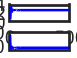

clear all;
clc;
cstr_global;

global Wc u1 u2
sample_T = 0.1;

n_op = 2;
n_ip = 2;
n_st = 2;
n_d = 2;
N_samples = 500;

G_Ko = 1.0e10;
G_E = 8330.1;
G_V = 1.0;
G_Cp = 1.0;
G_rho = 1e6;
G_delH = 1.3e8;
G_Cpc = 1.0;
G_rhoc = 1e6;
G_a = 1.678e6;
G_b = 0.5;
G_To = 323.0;

state_sigma = [0.001 0.5];
meas_sigma = [0.001 0.5];

u_ss = [1 15]';                                                                    
Uk(:,1) = u_ss;

u1 = 1;
u2 = 15;
C =[1 0;0 1];

Cao = 2.0;
Tcin = 92 + 273;
Wc = [Cao; Tcin];

for i = 1:1:500
    wk(1,i) = state_sigma(1)*randn;
    wk(2,i) = state_sigma(2)*randn;
end

for i = 1:1:500
    vk(1,i) = meas_sigma(1)*randn;
    vk(2,i) = meas_sigma(2)*randn;
end

x_initial = [0.5 400]';

for i = 1:1:500
    [T,Xj] = ode45('cstr_model',[0 sample_T],x_initial);
    X_state(i,:) = Xj(end,:);
    x_initial = Xj(end,:)';
end

set_graphics 

figure(1)
subplot(211)
plot(1:500,X_state(:,1),'b')
ylabel('Ca')

subplot(212)
plot(1:500,X_state(:,2),'b')
xlabel('Sampling Instant')
ylabel('T')


X_steady_state = X_state(end,:);

u1_flow = 1 + idinput(500,'PRBS',[0 0.166],[-0.05 0.05]);

u2_temp = 15 + idinput(500,'PRBS',[0 0.166],[-0.75 0.75]);

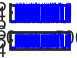


figure(2)
subplot(211)
plot(1:500,u1_flow(:,1),'b')
ylabel('Flow')

subplot(212)
plot(1:500,u2_temp(:,1),'b')
xlabel('Sampling Instant')
ylabel('T')

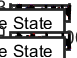


x_initial2 = X_steady_state;
for i = 1:1:N_samples
    u1 = u1_flow(i,1);
    u2 = u2_temp(i,1);
    [T,XM] = ode45('cstr_model',[0 sample_T],x_initial2);
    X_new_state(i,:) = XM(end,:);
    x_initial2=XM(end,:);
    X_noisy_state(i,:) = X_new_state(i,:) + wk(:,i)';
    Yk(:,i) = C*X_noisy_state(i,:)' + vk(:,i);
    u1_flowNoisy(i,1)=u1_flow(i,1)+1*randn;
    u2_tempNoisy(i,1)=u2_temp(i,1)+1*randn;
end

figure(3)
subplot(211)
plot(1:500,X_new_state(:,1),'b', 1:500, X_noisy_state(:,1),'r', 1:500, Yk(1,:)','k')
ylabel('Ca')
legend('True State', 'Noisy State')

subplot(212)
plot(1:500,X_new_state(:,2),'b', 1:500, X_noisy_state(:,2),'r',1:500, Yk(2,:)','k')
xlabel('Sampling Instant')
ylabel('T')
legend('True State', 'Noisy State')

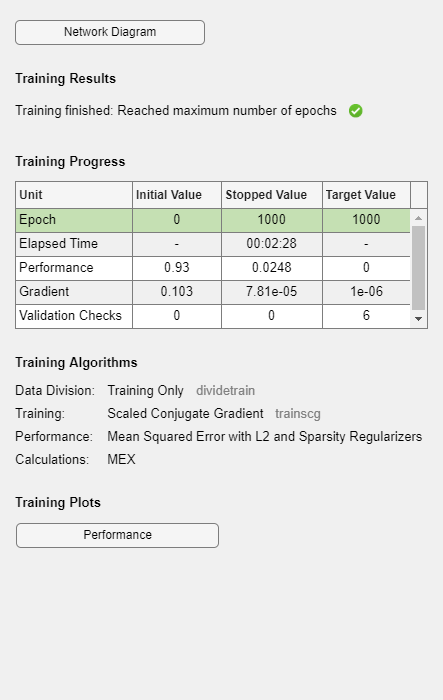

autoenc =   Autoencoder with properties:

                 HiddenSize: 10
    EncoderTransferFunction: 'logsig'
             EncoderWeights: [10×250 double]
              EncoderBiases: [10×1 double]
    DecoderTransferFunction: 'logsig'
             DecoderWeights: [250×10 double]
              DecoderBiases: [250×1 double]
         TrainingParameters: [1×1 struct]
                  ScaleData: 1



x(:,1)=(X_noisy_state(:,1)-mean(X_noisy_state(:,1)))/std(X_noisy_state(:,1));
x(:,2)=(X_noisy_state(:,2)-mean(X_noisy_state(:,2)))/std(X_noisy_state(:,2));
x(:,3)=(u1_flowNoisy-mean(u1_flowNoisy))/std(u1_flowNoisy);
x(:,4)=(u2_tempNoisy-mean(u2_tempNoisy))/std(u2_tempNoisy);

%{
[train_idx, ~, test_idx] = dividerand(500, 0.5, 0,0.5);
    % slice training data with train indexes 
    %(take training indexes in all 10 features)
    x_train = x(train_idx, :);
    % select test data
    x_test = x(test_idx, :);
%}

for i=1:1:250
    x_train(i,:)=x(i,:);
end
for i=1:1:250
    x_test(i,:)=x(250+i,:);
end
%A=ismatrix(x_test2)
autoenc = trainAutoencoder(x_train)


xReconstructed = predict(autoenc,x_test)

xReconstructed =    -0.1342   -0.0584   -0.0802   -0.0915
   -0.1063    0.1140    0.0836   -0.0170
   -0.2608    0.1488    0.0753   -0.1027
   -0.4220   -0.2312   -0.2672   -0.3504
   -0.2869   -0.0987   -0.1319   -0.2329
   -0.3345   -0.3574   -0.3563   -0.3375
   -0.3273   -0.4473   -0.4288   -0.3592
   -0.2861   -0.4260   -0.3983   -0.3467
   -0.3573   -0.5939   -0.5470   -0.4427
    0.0004    0.0211    0.0147    0.0132


mseError = mse(x_test-xReconstructed)

mseError = 1.1735

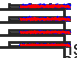


%---------------------------------------------------------------------------
%{
for i=1:1:500
    if i<=350
        xu1_1(i,1)=u1_flowNoisy(i,1);
    end
    if i>350
        xu1_2(i,1)=u1_flowNoisy(i,1);
    end
end

autoenc=trainAutoencoder(xu1_1(:,1))
xReconstructed = predict(autoenc,xu1_2(:,1))
mseError = mse(xu1_2-xReconstructed)
subplot(211)

plot(1:500,((xu1_2-xReconstructed)/500),'b')

subplot(212)
plot(1:500,xu1_2,'b',1:500,xReconstructed,'r')

%normalise the data
%avg sum of sq data
%find mse error by yourself
%normalize it (value - mean)/standard deviation
%}

figure(4)
subplot(411)
plot(251:500,x(251:500,1),'b',251:500,xReconstructed(:,1),'r')
xlabel('Sampling Instant')
ylabel('Ca')
legend('True State', 'Reconstructed True State')

subplot(412)
plot(251:500,x(251:500,2),'b',251:500,xReconstructed(:,2),'r')
xlabel('Sampling Instant')
ylabel('T')
legend('True State', 'Reconstructed True State')

subplot(413)
plot(251:500,x(251:500,3),'b',251:500,xReconstructed(:,3),'r')
xlabel('Sampling Instant')
ylabel('u1_flow')
legend('True State', 'Reconstructed True State')

subplot(414)
plot(251:500,x(251:500,4),'b',251:500,xReconstructed(:,4),'r')
xlabel('Sampling Instant')
ylabel('u2_temp')
legend('True State', 'Reconstructed True State')

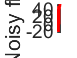


%NoisyReconstructed=predict(autoenc,Noisy_u1)
%mseErrorNoisy=mse(u1_flowNoisy-Noisy_u1)

for i=1:1:500
    if i<=250
        Noisy_u1(i,1)=u1_flowNoisy(i,1);
    elseif i>250 && i<=280
        Noisy_u1(i,1)=u1_flowNoisy(i,1)+15*randn;
    elseif i>280 && i<=350
        Noisy_u1(i,1)=u1_flowNoisy(i,1);
    elseif i>350 && i<=500
        Noisy_u1(i,1)=i/10+u1_flowNoisy(i,1);
    end
end

figure(5)
plot(251:500,Noisy_u1(251:500,:),'r')
ylabel('Noisy flow')


Noisy_u1Reconstruted=predict(autoenc,Noisy_u1(251:500,1))

Noisy_u1Reconstruted =    -0.0701
    0.1188
    0.1448
   -0.2358
   -0.0861
   -0.3636
   -0.4668
   -0.4131
   -0.5993
    0.0140


mseErroru1_flow=mse(Noisy_u1(251:500,1)-Noisy_u1Reconstruted)

mseErroru1_flow = 1.1902e+03


figure(6)
plot(251:500,Noisy_u1(251:500,1),'b',251:500,Noisy_u1Reconstruted,'r')
ylabel('Flow data')
legend('Normal data','Reconstructed Noisy data')



x_Noisy(:,1)=(X_noisy_state(:,1)-mean(X_noisy_state(:,1)))/std(X_noisy_state(:,1));
x_Noisy(:,2)=(X_noisy_state(:,2)-mean(X_noisy_state(:,2)))/std(X_noisy_state(:,2));
x_Noisy(:,3)=(Noisy_u1-mean(Noisy_u1))/std(Noisy_u1);
x_Noisy(:,4)=(u2_tempNoisy-mean(u2_tempNoisy))/std(u2_tempNoisy);

%{
x_Noisy(:,1)=X_noisy_state(:,1);
x_Noisy(:,2)=X_noisy_state(:,2);
x_Noisy(:,3)=Noisy_u1;
x_Noisy(:,4)=u2_tempNoisy;
%}
for i=1:1:250
    x_Noisy1(i,:)=x_Noisy(250+i,:);
end
NoisyxReconstructed = predict(autoenc,x_Noisy1)

NoisyxReconstructed =    -0.1342   -0.0584   -0.0721   -0.0915
   -0.1063    0.1140    0.1115   -0.0170
   -0.2608    0.1488    0.1288   -0.1027
   -0.4220   -0.2312   -0.2437   -0.3504
   -0.2869   -0.0987   -0.0964   -0.2329
   -0.3345   -0.3574   -0.3621   -0.3375
   -0.3273   -0.4473   -0.4600   -0.3592
   -0.2861   -0.4260   -0.4080   -0.3467
   -0.3573   -0.5939   -0.5887   -0.4427
    0.0004    0.0211    0.0136    0.0132


%for i=1:1:250
    mseErrorNoisy=mse(x(251:500,:)-NoisyxReconstructed(i,:))

mseErrorNoisy = 0.9503

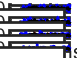

%end



figure(7)
subplot(411)
plot(251:500,x(251:500,1),'b',251:500,xReconstructed(:,1),'r',251:500,NoisyxReconstructed(:,1),'k')
xlabel('Sampling Instant')
ylabel('Ca')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')

subplot(412)
plot(251:500,x(251:500,2),'b',251:500,xReconstructed(:,2),'r',251:500,NoisyxReconstructed(:,2),'k')
xlabel('Sampling Instant')
ylabel('T')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')

subplot(413)
plot(251:500,x(251:500,3),'b',251:500,xReconstructed(:,3),'r',251:500,NoisyxReconstructed(:,3),'k')
xlabel('Sampling Instant')
ylabel('u1_flow')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')

subplot(414)
plot(251:500,x(251:500,4),'b',251:500,xReconstructed(:,4),'r',251:500,NoisyxReconstructed(:,4),'k')
xlabel('Sampling Instant')
ylabel('u2_temp')
legend('True State', 'Reconstructed True State','Noisy Reconstructed State')



% CNN and autoencoder
% sensors plus abnormality
% including filters

save result_openloop_simulation.mat
